# **Measurement of *****e/m***** for electrons**

Febuary 21st, 2019

PHYS 3605W

Cameron Laedtke

### Overview

In conducting this experiment our intent was to experimentally obtain a value of e/m for an electron based on measurements of their deflection in a uniform magnetic field. 

### Procedure and General Notes

We recorded Earth's magnetic field in minneapolis to see if it would have an effect on our results. We found the maximum horizontal component of Earth's magnetic field using NOAA geophysical data from January 2018, and obtained the following.

                         
$$B_{\mathrm{Earth}\;\left(\mathrm{East}\right)} =3\ldotp 99*{10}^{-8} \pm 8\ldotp 9*{10}^{-8} \;T\;$$
 

We measured the distance between Helmholz coils using a ruler so we could determine the magnetic field for a given current (of the form $B=\mathrm{kI}$). Since the radius of the coils $R_C$ is equal to the seperation distance (d) , we derived an equation for the magnetic field in terms of current and coil deperation distance. N is the number of turns on the coil (there were 124 turns on our coil).

                        
$$B=\frac{N\mu_o I}{{1\ldotp 25}^{1\ldotp 5} R_C }$$
      
$$k=\frac{N\mu_o }{{1\ldotp 25}^{1\ldotp 5} R_C }$$
     
$$\sigma_k^2 =R_C^2 {\left(\frac{-N\mu_o }{{1\ldotp 25}^{1\ldotp 5} R_C^2 }\right)}^2$$
 
$$k=7\ldotp 34*{10}^{-4\;} \pm 0\ldotp 05*{10}^{-4} \;\frac{T}{A}$$


We then performed error propagation on B and obtained the following.

                        
$$\sigma_B^2 =\sigma_k^2 {\left(I\right)}^2 +\sigma_I^2 {\left(k\right)}^2$$


The measured parameters for our magnetic field equation are reported below.

                        
$$R_C =0\ldotp 152\;m$$
     
$$N=124\;\mathrm{turns}$$
    

We defined the uncertainties of our measured quantities as follows. The uncertainty for beam radius is based off our ability to line up the beam with the ladder rung using our eyesight. The uncertainty in current and voltage is based off the minimum uncertainty in the resolution of the multimeters. 

                        
$$\sigma_{R_C } =0\ldotp 0005\;m$$
  
$$\sigma_{r_{\textrm{beam}} } =0\ldotp 001\;m$$
  
$$\sigma_I =0\ldotp 01\;A\;$$
  
$$\sigma_V =0\ldotp 001\;V$$


Using our equation $B=\textrm{kI}$, we compared the maximum horizontal component of Earth's field with what we would expect when a current of several amperes is passed through the coils. We determined that Earth's field would we roughly six orders of magnitude less than our expected field, so any effect on our results would be negligeable. To be safe, we oriented our apparatus in the Eastern direction to align with Earth's megnetic field and minimize its effect. It was difficult to configure our apparatus in the Eastern direction, since there were magnetic fields in the room that interfered with our compass. We used the compass app on our phones to determine the direction.

Our apparatus included three power supplies. One that supplied the heater potential, one that supplied up to 306V to the anode potential, and one that supplied the negative potential to the Wehnhelt cylinder (to focus the electron beam). There was also a current supply to the Helmholtz coild. Rather than rely on the attached supplies, we used seperate multimeters to measure anode potential and coil current. We set the heater supply to 7.38 $\pm 0\ldotp 01V$. Finally, we took a series of measuremnts of the anode potential V and the coil current I while keeping the electron beam focused on a given rung on the ladder. The diagrams below from the PHYS 3605W lab manual shows the basic workings of our apparatus.

        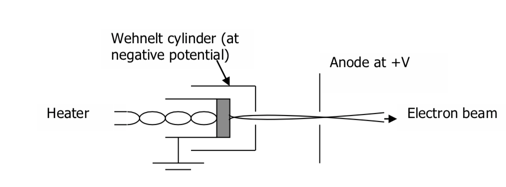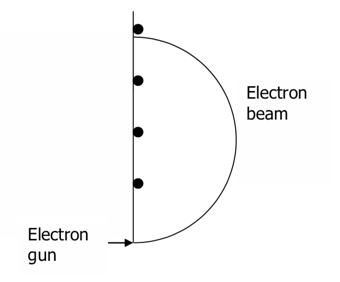

One factor that limited the amout of data we could take was the limited visibility of the electron beam. In order to see the beam, we had to set the anode potential close to its maximum. This was especially true when the beam was at the first (lowest) rung and the highest three rungs. We took data only for the first three rungs, since we could not obtain a visible beam for the top two. It would have helped our experiment if the anode potential could have been set to a higher voltage, since that would have allowed us to collect data for the top two rungs. 

### Results and Systematics

The raw data for our measuremnts of coil current, anode potential, coil beam diameter, and beam radius can be found in the file *em_lab_data_final.csv*

data = dlmread('em_lab_data_final.csv',',', [3,1,30,4]); 

I = data(:,1); % coil current (Amps)
V = data(:,2); % anode potential (Volts)
r = data(:,4); % beam radius (Meters)

format shortG

In order to obtain a value for *e/m*, we used the equation below, where r is the radius of the electron beam.

                 
$$V=\frac{e}{2m}{\left(\textrm{rB}\right)}^2$$


Rearanging the equation so that the largest errors appear on the y axis, and adding a y-intercept term, we obtain our final fit equation of the form $y=\mathrm{bx}+a$

                ${\left(\mathrm{rB}\right)}^2 =2\frac{m}{e}V+{\left(\mathrm{rB}\right)}_o^2$          *where        *  $\frac{e}{m}=\frac{2}{b}$     *and*           $\sigma_{\frac{e}{m}}^2 =\sigma_b^2 {\left(\frac{-1}{b^2 }\right)}^2$

Error propagation then gives us the following uncertainties for our linear fit

                  
$$\sigma_y^2 =\sigma_{{\left(\mathrm{rB}\right)}^2 }^2 =\sigma_r^2 {\left(2{\mathrm{rB}}^2 \right)}^2 +\sigma_B^2 {\left(2r^2 B\right)}^2$$


                  
$$\sigma_x =\sigma_V$$


In order to determine if our values of  *e/m* show any dependance on beam radius, we sorted our data by beam radius so we could fit them seperately. 

data = [V, r, I];
r1_data = data(r==0.02,:); % beam radius r = 0.020 meters
r2_data = data(r==0.03,:); % beam radius r = 0.030 meters
r3_data = data(r==0.04,:); % beam radius r = 0.040 meters

For efficiency, the function *prepdata() *at the bottom of the scipt takes in data for V, I, r, and transforms them into the variables needed for the linear fit equation $y=\mathrm{bx}+a$

[r1_x, r1_y, r1_x_err, r1_y_err] = prepdata(r1_data);
[r2_x, r2_y, r2_x_err, r2_y_err] = prepdata(r2_data);
[r3_x, r3_y, r3_x_err, r3_y_err] = prepdata(r3_data);

Next, we perform a linear fit on the data for each rung using the *myfit() *function, along with calculation of chi and chi squared values. 

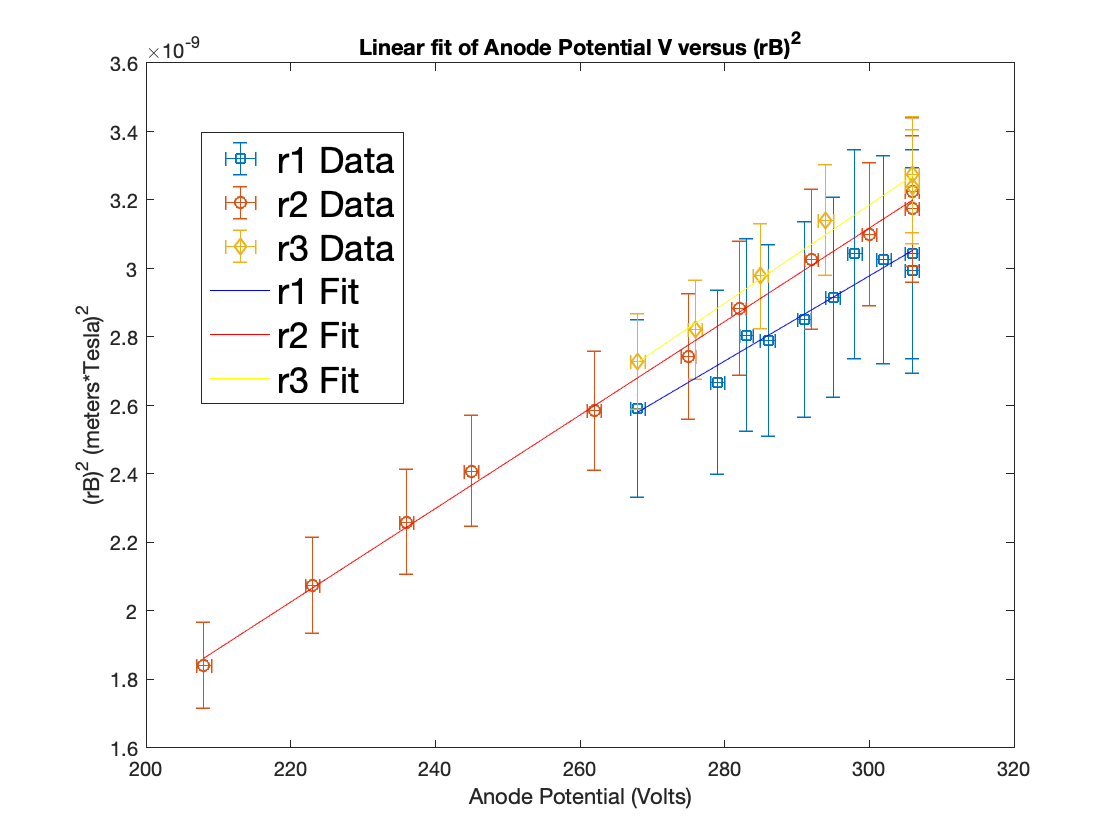

[a_1, b_1, ea_1, eb_1] = myfit(r1_x,r1_y,r1_y_err);
r1_fit_y = a_1 + r1_x.*b_1;

[a_2, b_2, ea_2, eb_2] = myfit(r2_x,r2_y,r2_y_err);
r2_fit_y = a_2 + r2_x.*b_2;

[a_3, b_3, ea_3, eb_3] = myfit(r3_x,r3_y,r3_y_err); 
r3_fit_y = a_3 + r3_x.*b_3;

[xneg, xpos, yneg, ypos] = deal(r1_x_err, r1_x_err, r1_y_err, r1_y_err);
errorbar(r1_x,r1_y,yneg,ypos,xneg,xpos,'s','DisplayName', 'r1 Data')   
hold on
[xneg, xpos, yneg, ypos] = deal(r2_x_err, r2_x_err, r2_y_err, r2_y_err);
errorbar(r2_x,r2_y,yneg,ypos,xneg,xpos,'o','DisplayName', 'r2 Data')
[xneg, xpos, yneg, ypos] = deal(r3_x_err, r3_x_err, r3_y_err, r3_y_err);
errorbar(r3_x,r3_y,yneg,ypos,xneg,xpos,'d', 'DisplayName', 'r3 Data')

title('Linear fit of Anode Potential V versus (rB)^2')
ylabel('(rB)^2 (meters*Tesla)^2')
xlabel('Anode Potential (Volts)')

plot(r1_x, r1_fit_y, 'b', 'DisplayName', 'r1 Fit')
plot(r2_x, r2_fit_y, 'r', 'DisplayName', 'r2 Fit')
plot(r3_x, r3_fit_y, 'y', 'DisplayName', 'r3 Fit')
hand = legend('location','northwest');
set(hand, 'fontsize', 18)
set(hand, 'position', [0.18,0.60,0.18,0.16])
hold off

[r1_chi, r1_chi2] = getChi(r1_y, r1_fit_y, r1_y_err);
[r2_chi, r2_chi2] = getChi(r2_y, r2_fit_y, r2_y_err);
[r3_chi, r3_chi2] = getChi(r3_y, r3_fit_y, r3_y_err);

hold off

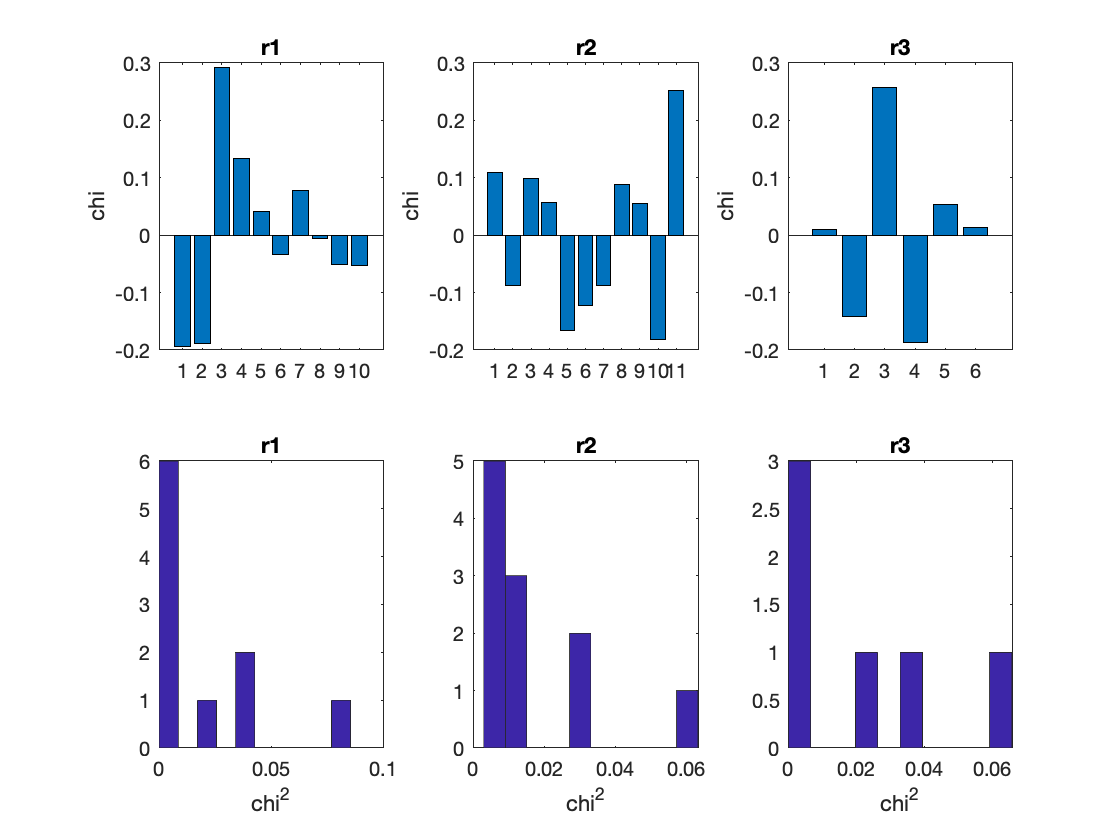

subplot(2,3,1)
bar(r1_chi)
title('r1')
ylabel('chi')
subplot(2,3,2)
bar(r2_chi)
title('r2')
ylabel('chi')
subplot(2,3,3)
bar(r3_chi)
title('r3')
ylabel('chi')

subplot(2,3,4)
hist(r1_chi2)
title('r1')
xlabel('chi^2')
subplot(2,3,5)
hist(r2_chi2)
title('r2')
xlabel('chi^2')
subplot(2,3,6)
hist(r3_chi2)
title('r3')
xlabel('chi^2')


r1_chi_score = getChiScore(r1_y, r1_fit_y, r1_y_err, 2)

r1_chi_score =      0.023942


r2_chi_score = getChiScore(r2_y, r2_fit_y, r2_y_err, 2)

r2_chi_score =      0.021083


r3_chi_score = getChiScore(r3_y, r3_fit_y, r3_y_err, 2)

r3_chi_score =       0.03099


Using the slope of each linear fit (b_1, b_2, and b_3), and their corresponding uncertainties (eb_1, eb_2, and eb_3), we can calculate a value for *e/m *for each rung, and then combine for a weighted average. 

r1_em = 2/b_1

r1_em =    1.6092e+11


r2_em = 2/b_2

r2_em =    1.4652e+11


r3_em = 2/b_3

r3_em =    1.3944e+11



get_em_err = @(b,eb)sqrt(eb^2*(-1/b^2)^2);
r1_em_err = get_em_err(b_1,eb_1)

r1_em_err =    4.8536e+10


r2_em_err = get_em_err(b_2,eb_2)

r2_em_err =     8.125e+09


r3_em_err = get_em_err(b_3,eb_3)

r3_em_err =      2.14e+10



ems = [r1_em, r2_em, r3_em];
em_errs = [r1_em_err, r2_em_err, r3_em_err];
sum1 = sum(ems./em_errs.^2);
sum2 = sum(1./em_errs.^2);
em_weighted_avg = sum1/sum2

em_weighted_avg =    1.4599e+11


em_weighted_avg_err = sqrt(1/sum2)

em_weighted_avg_err =    7.5046e+09


For the shortest rung (r1 = 0.020 meters)   $\frac{e}{m}=1\ldotp 61*{10}^{11} \pm \;0\ldotp 49*{10}^{11} \;\frac{C}{\textrm{kg}}$ 

For the middle rung (r2 = 0.030 meters)     $\frac{e}{m}=1\ldotp 47*{10}^{11} \pm \;0\ldotp 08\ldotp *{10}^{11} \;\frac{C}{\textrm{kg}}$ 

For the highest rung (r3 = 0.040 meters)    $\frac{e}{m}=1\ldotp 39*{10}^{11} \pm \;0\ldotp 21*{10}^{11} \;\frac{C}{\textrm{kg}}$ 

Finally, we obtain a weighted average:  $\frac{e}{m}=1\ldotp 46*{10}^{11} \pm \;0\ldotp 08*{10}^{11} \;\frac{C}{\textrm{kg}}$ 

The true value for *e/m is *1.756*10 ${10}^{11} \;\frac{C}{\textrm{kg}}$, which is well outside the uncertainty for our weighted average. However, there appears to be a relationship between radius of the electron beam and value for *e/m. *This could be due to fact that the megnetic field becomes less uniform further out from the center of the coil. Closer to the center of the coil, the actualy value of magnetic field is more likely to be close to our expected value, thus giving a value for *e/m* closer to its true value. This could explain why our measured value of *e/m *appears to move closer its true value as electron beam radii decreases. Notably, the true value for *e/m* falls within the error bounds of our measured *e/m *value for the smallest rung. An ability to measure an electron beam with a smaller radius than 0.020 meters would be informative.

Additionally, a visual inspection of our plot of (rB)^2 as a function of anode potential shows a very high amount of uncertainty in (rB)^2. This is reflected in the plot of chi and chi squared values for each fit. We should expect some of the datapoints to have absolute chi values of more than one (around 32% assuming a Gaussian distribution). However, not a single point has an absolute chi value of more than 0.3. Averaging our chi squared values, and assuming two degrees of freedom, we get chi squared scores of 0.024, 0.021, and 0.031 for our three linear fits of r1, r2, and r3 respectively. Since this is much less than one, this tells us there is something fundamentally flawed with out model. 

Looking at the equation for error propagation of  (rB)^2, the largest sources of this uncertainty come from our measured uncertanties of coil radius, beam radius, and coil current. To obtain a more accurate fit, and thus a more accurate value for *e/m*, our experiment would have benefited from more precise measuring equipment for these three quantities.

function [chi, chi2] = getChi(y, fit_y, y_err)
   chi = (y - fit_y)./(y_err);
   chi2 = chi.^2;
end

function chi_score = getChiScore(y, fit_y, y_err, dof)
   chi = (y - fit_y)./(y_err);
   chi2 = chi.^2;
   chi_score = sum(chi2)./(numel(chi2)-dof);
end

function [x, y, x_err, y_err] = prepdata(data)
   V = data(:,1);
   r = data(:,2);
   I = data(:,3);
   
   mu = 4*pi*10^-7; 
   Rc = 0.152;
   N = 124;
   k = (N*mu)/(1.25^1.5*Rc); 
   
   sz = size(V);
   V_err = ones(sz); % Volts
   r_err = 0.001; % Meters
   I_err = 0.01; % Amps
   Rc_err = 0.0005; % meters
   k_err = Rc_err*sqrt(((-N*mu)/(1.25^1.5*Rc^2))^2);
   
   B = k.*I + 3.99*10^-8; % Tesla
   B_err= sqrt(k_err^2.*I.^2 + I_err^2*k^2);
   
   x = V;
   y = r.^2.*B.^2;
   x_err = V_err;
   % y_err is the uncertainty on (rB)^2 for each data point
   y_err = sqrt(r_err.^2.*(2.*r.*B.^2).^2 + B_err.^2.*(2.*r.^2.*B).^2);
   
end

function [a, b, ea, eb] = myfit(x,y,ey)
  sx = sum(x ./ (ey .^ 2) );
  sy = sum(y ./ (ey .^ 2) );
  sxx = sum((x .* x) ./ (ey .^ 2) );
  sxy = sum((x .* y) ./ (ey .^ 2) );
  s = sum(1 ./ (ey .^ 2) );
  delta=sxx*s-sx*sx;
  a=(sxx*sy-sx*sxy)/delta;
  ea=sqrt(sxx/delta);
  b=(s*sxy-sx*sy)/delta;
  eb=sqrt(s/delta);
end